clear; clc;
%to call a newton/gradient method and plot the cartesian error
syms q1 q2 real;

%all the parameters of the robot
l1 = 0.5;
l2 = 0.4;

%all the desired/actual configuration + direct kinematics
q_in = [q1; q2];
desired_point = [0.4; -0.3];
f_r = [
    l1 * cos(q1) + l2 * cos(q1 + q2);
    l1 * sin(q1) + l2 * sin(q1 + q2);
];
initial_guess = [-sym(pi)/160; -sym(pi)/2];

max_iterations = 1000;
max_cartesian_error = 10^(-4);
min_joint_increment = 10^(-6);
max_closeness_singularity = 10^(-4);

%Newton method
[q_out, guesses, cartesian_errors] = newton_method(q_in, desired_point, f_r, initial_guess, max_iterations, max_cartesian_error, min_joint_increment, max_closeness_singularity)

Non-redundant case, let's use the inverse
Finshed at iteration 3 because the error was lower than the specified amount.


q_out =     0.1797
   -1.9825


guesses =    -0.0196   -1.5708
    0.1962   -2.0221
    0.1797   -1.9825


cartesian_errors =     0.1432    0.0148    0.0001


cartesian_errors(3)

ans = 9.8921e-05


%if you want to use the gradient method you have also to specify an
%alpha: The "learning rate" of the algorithm
% alpha = 1;
% [q_out, guesses, cartesian_errors] = gradient_method(q_in, desired_point, f_r, initial_guess, alpha, max_iterations, max_cartesian_error, min_joint_increment, max_closeness_singularity)

%if you want to plot them
names = ['1' '2' '3'];
figure
hold on
plot(guesses);grid; title('joint variables evolution');xlabel('iterations');ylabel('q[rad]')
legend(arrayfun( @num2str,  names, 'UniformOutput', false ))

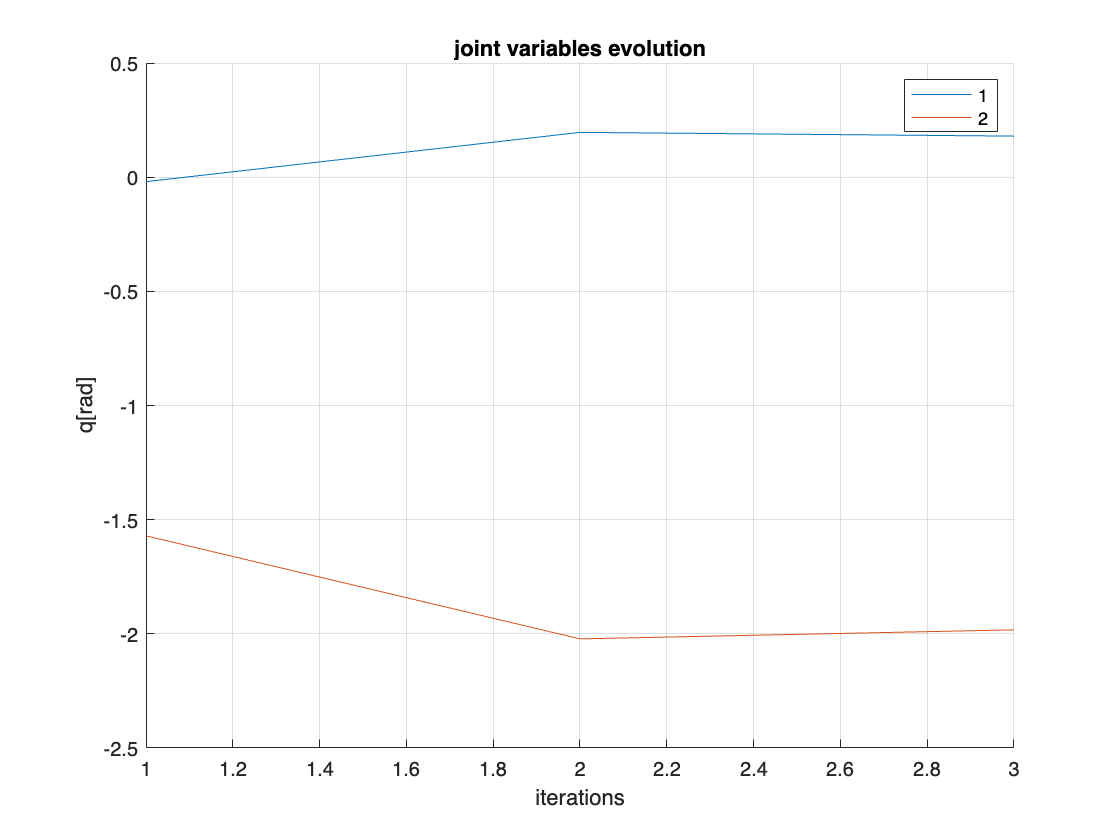

hold off

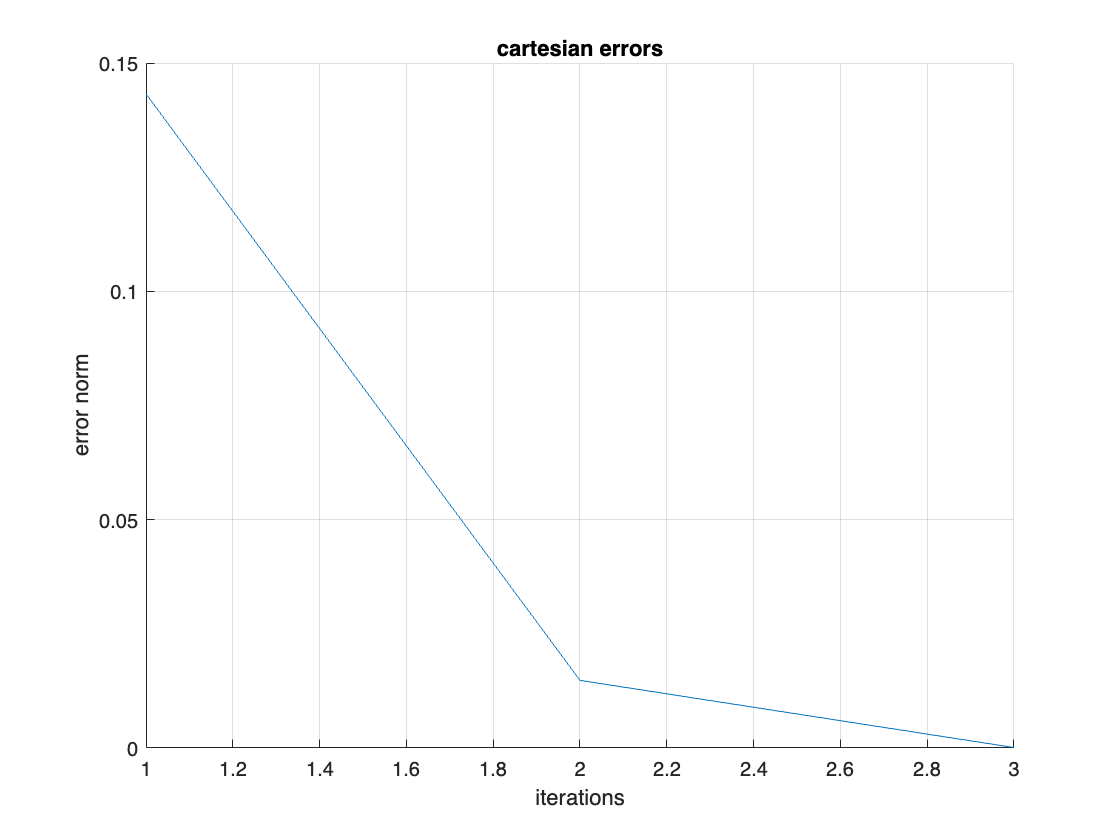

legend show

figure
hold on
plot(cartesian_errors);grid; title('cartesian errors');xlabel('iterations');ylabel('error norm')